# Control de sistemas biológicos TP N°1 PROBLEMA 2 (dado)

A continuación se resuelve el ejercicio 3 de la práctica N°1 (producción bacterial de bioplástico).

El modelo a controlar es el siguiente:

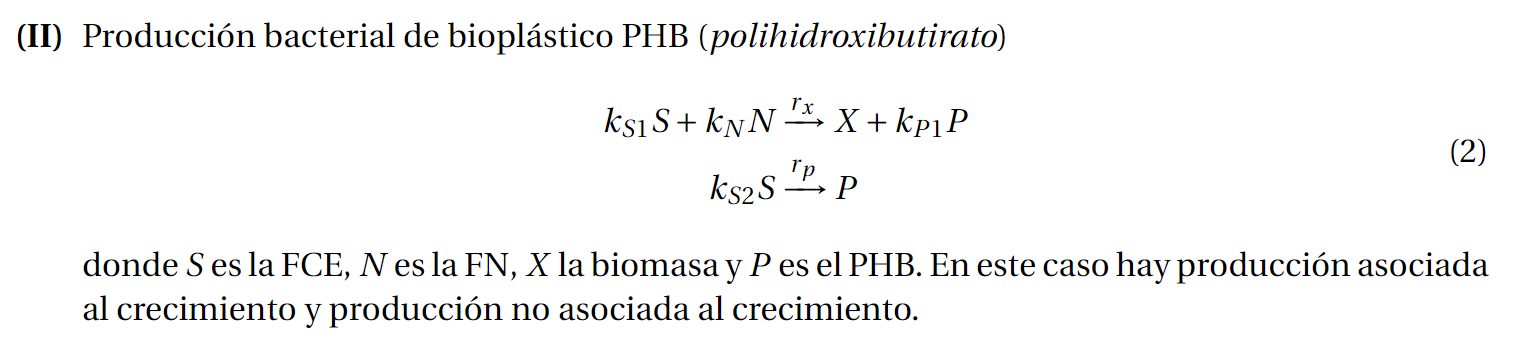

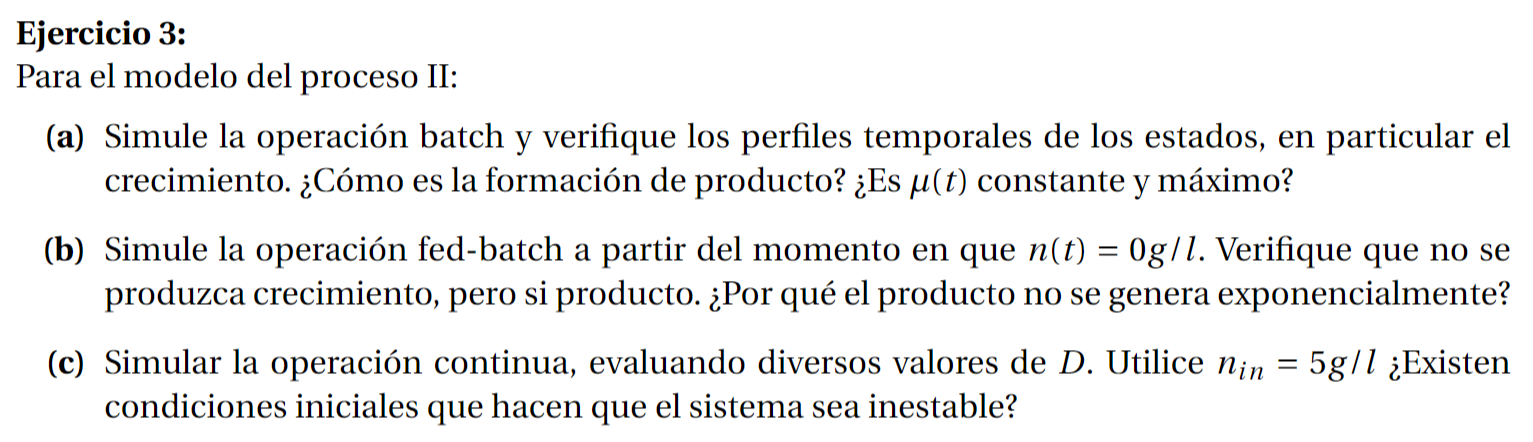

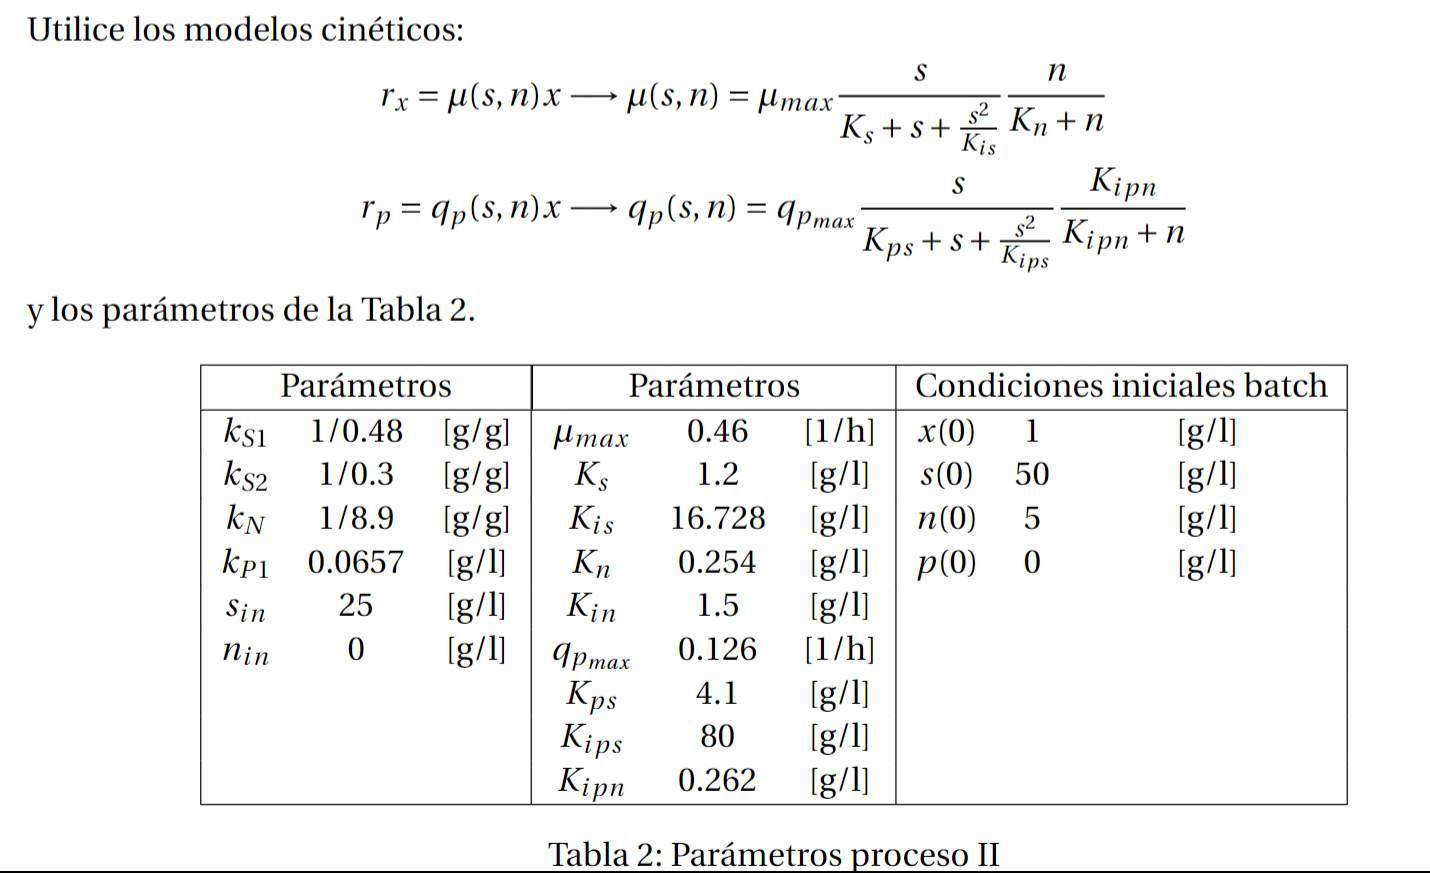

## Preguntas

- ¿Cómo funciona D?

- Sacar ec diff?


$$\begin{array}{l}
\dot{V} =F_s \\
D_s =\frac{F_s }{V}
\end{array}$$


clear all; close all; clc;

Defino los parámetros del modelo para un batch con modelo de Monod/Haldane

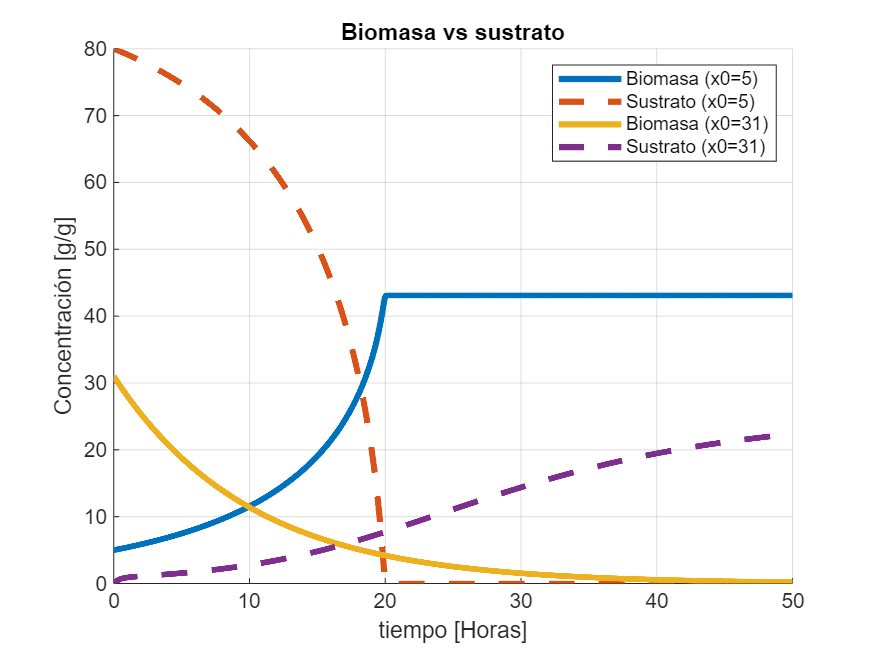

% Datos dados
ks1=1/0.48;
ks2=1/0.3;
kn=1/8.9;
kp1=0.0657;
s_in=25;
n_in=0;
mu_max=0.46;
Ks=1.2;
Kis=16.728;
Kn=0.254;
Kin=1.5;
qp_max=0.126;
Kps=4.1;
Kips=80;
Kipn=0.262;
p0=0;
% s0=50;
% x0=1;
% n0=5;
% Ds=0.00;
% Dn=0.0;

% IMPORTANTE: Definio una estructura que contiene todas las combinaciones
% de valores que voy a ir cambiando en las diferentes simulaciones
% Ajusto los datos para la producción de biomasa
sim_data{1}.x0=5; % Valores inciales de biomasa
sim_data{1}.Ds=0; % Valores de dilución (igual terminan siendo la misma)
sim_data{1}.Dn=0; % Valores de dilución (igual terminan siendo la misma)
sim_data{1}.n0=30; % Concentraciones inciales de nitrogeno
sim_data{1}.s0=80; % Concentraciones inciales de sustrato
% Ajusto datos para la produccion de plástico
sim_data{2}.x0=31; % Valores inciales de biomasa
sim_data{2}.Ds=0.1; % Valores de dilución (igual terminan siendo la misma)
sim_data{2}.Dn=0; % Valores de dilución (igual terminan siendo la misma)
sim_data{2}.n0=0; % Concentraciones inciales de nitrogeno
sim_data{2}.s0=0; % Concentraciones inciales de sustrato    

% Simulación
sim_results = cell(length(sim_data), 1);
for i=1:length(sim_data)
    
    x0=sim_data{i}.x0;
    n0=sim_data{i}.n0;
    s0=sim_data{i}.s0;
    F=[0;0;0;0];
    Q=[0;0;0;0];
    Ds=sim_data{i}.Ds;
    Dn=sim_data{i}.Dn;

    % Parámetros para el modelo
    modelParameters.rx_params.max=mu_max;
    modelParameters.rx_params.k1=Ks;
    modelParameters.rx_params.k2=Kis;
    modelParameters.rx_params.k3=Kn;
    
    modelParameters.rp_params.max=qp_max;
    modelParameters.rp_params.k1=Kps;
    modelParameters.rp_params.k2=Kips;
    modelParameters.rp_params.k3=Kipn;
    
    modelParameters.Kipn=Kipn;
    modelParameters.K=[1,0;-ks1,-ks2;-kn,0;kp1,1];
    
    % Definimos entradas y condiciones iniciales
    xi_in=[0,0; s_in,0; 0,n_in; 0,0];
    D=[Ds; Dn];
    xi0=[x0;s0;n0;p0];
    
    simConfig.StopTime = "50";
    simConfig.Solver = 'ode1';
    simConfig.FixedStep = '0.01';
    sim_out = sim('TP1\TP1EJ3', simConfig);
    
    sim_results{i}.time = sim_out.simout.Time;
    sim_results{i}.biomass = reshape(sim_out.simout.Data(:,1), size(sim_results{i}.time));
    sim_results{i}.sustrate = reshape(sim_out.simout.Data(:,2), size(sim_results{i}.time));
    sim_results{i}.nitrogen = reshape(sim_out.simout.Data(:,3), size(sim_results{i}.time));
    sim_results{i}.plastic = reshape(sim_out.simout.Data(:,4), size(sim_results{i}.time));
    sim_results{i}.rx = reshape(sim_out.rx.Data, size(sim_results{i}.time));
    sim_results{i}.rp = reshape(sim_out.rp.Data, size(sim_results{i}.time));
    sim_results{i}.v = reshape(sim_out.V.Data, size(sim_results{i}.time));
    sim_results{i}.sim_data = sim_data{i};

end
    
% Se grafica
figure();
hold on; grid on;
title('Biomasa vs sustrato');
xlabel('tiempo [Horas]');
ylabel('Cantidades en masa [g]');
legends=cell(1,length(sim_data)*2); legend_counter=1;
for i=1:length(sim_data)
    plot(sim_results{i}.time, sim_results{i}.biomass*sim_results{i}.biomass, 'LineWidth', 3);
    plot(sim_results{i}.time, sim_results{i}.sustrate, 'LineWidth', 3);
    plot(sim_results{i}.time, sim_results{i}.sustrate, 'LineWidth', 3);
    plot(sim_results{i}.time, sim_results{i}.sustrate, 'LineWidth', 3);
    legends{1,legend_counter}=sprintf('Biomasa (x0=%d)', sim_results{i}.sim_data.x0);
    legends{1,legend_counter+1}=sprintf('Sustrato (x0=%d)', sim_results{i}.sim_data.x0);
    legend_counter=legend_counter+2;
end
legend(legends);

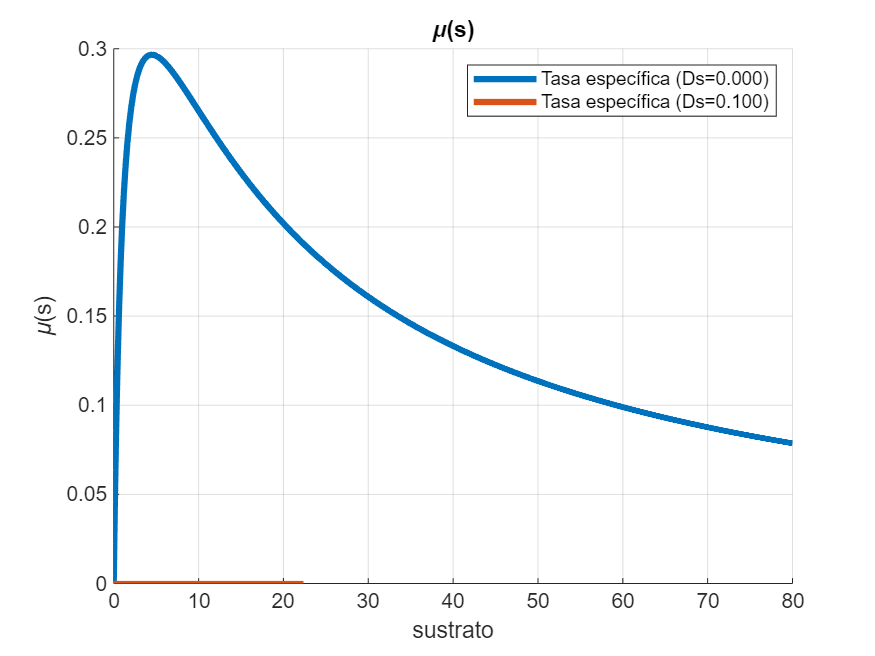

figure();
hold on; grid on;
title('\mu(s)');
xlabel('sustrato');
ylabel('\mu(s)');
legends=cell(1,length(sim_data)); legend_counter=1;
for i=1:length(sim_data)
    plot(sim_results{i}.sustrate, sim_results{i}.rx, 'LineWidth', 3);
    legends{1,legend_counter}=sprintf('Tasa específica (Ds=%.3f)', sim_results{i}.sim_data.Ds);
    legend_counter=legend_counter+1;
end
legend(legends);